# Data Analysis and AI demo

weatherData = generateSyntheticWeatherData(100);

% Display the first few rows of the generated weather data
disp(head(weatherData));

    Temperature    Humidity    WindSpeed    Label
    ___________    ________    _________    _____

        33            16          13          1  
        37            80           7          3  
         5            31          17          3  
        37            53          11          3  
        25            16           7          3  
         3            60          19          3  
        11            26          18          3  
        22            66          11          3  



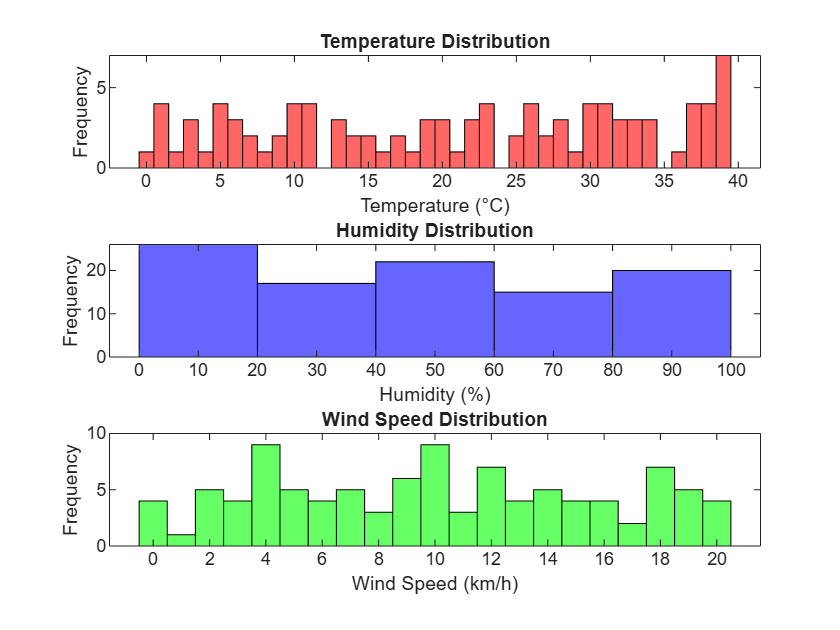

% Visualize the distribution of temperature, humidity, and wind speed
figure;
% Create subplots for each feature
subplot(3, 1, 1);
histogram(weatherData.Temperature, 'FaceColor', 'r', 'EdgeColor', 'k');
title('Temperature Distribution');
xlabel('Temperature (°C)');
ylabel('Frequency');
% Create a subplot for humidity distribution
subplot(3, 1, 2);
histogram(weatherData.Humidity, 'FaceColor', 'b', 'EdgeColor', 'k');
title('Humidity Distribution');
xlabel('Humidity (%)');
ylabel('Frequency');
% Create a subplot for wind speed distribution
subplot(3, 1, 3);
histogram(weatherData.WindSpeed, 'FaceColor', 'g', 'EdgeColor', 'k');
title('Wind Speed Distribution');
xlabel('Wind Speed (km/h)');
ylabel('Frequency');

## Utilities

function weatherData = generateSyntheticWeatherData(numSamples)
    % Generate synthetic weather dataset for classification
    % Inputs:
    %   numSamples - Number of samples to generate
    % Outputs:
    %   weatherData - A table containing synthetic weather data

    % Set random seed for reproducibility
    rng(0);

    % Generate synthetic features
    temperature = randi([0, 40], numSamples, 1); % Temperature in degrees Celsius
    humidity = randi([0, 100], numSamples, 1); % Humidity in percentage
    windSpeed = randi([0, 20], numSamples, 1); % Wind speed in km/h

    % Generate synthetic labels based on conditions
    labels = zeros(numSamples, 1);
    for i = 1:numSamples
        if temperature(i) > 30 && humidity(i) < 50
            labels(i) = 1; % Class 1: Hot and dry
        elseif temperature(i) < 10 && humidity(i) > 80
            labels(i) = 2; % Class 2: Cold and wet
        else
            labels(i) = 3; % Class 3: Mild
        end
    end

    % Create a table to hold the data
    weatherData = table(temperature, humidity, windSpeed, labels, ...
        'VariableNames', {'Temperature', 'Humidity', 'WindSpeed', 'Label'});
end